# Diagrama de interacción de columnas de sección compuesta

**Título completo:** Diagrama de interacción de columnas de sección compuesta rectangular (tubo estructural de acero relleno de hormigón, o *concreto*).

**Autor:** Isacc Alpala

**Asignatura:** Estructuras de acero

## Contexto

El diagrama de interacción para columnas de sección compuesta rectangular, como un tubo estructural de acero relleno de hormigón (o concreto), es una herramienta crucial en el diseño de estructuras híbridas que combinan los beneficios de ambos materiales: la alta resistencia a la compresión del hormigón y la ductilidad y resistencia a la tracción del acero. Estas columnas compuestas son comunes en edificios de gran altura y en otras estructuras donde se requiere un equilibrio entre resistencia, rigidez y economía.

Se debe considerar:

- **Columnas de Sección Compuesta**: En columnas de sección compuesta rectangular, la sección transversal está formada por un tubo estructural de acero, que actúa como la carcasa exterior, y un núcleo de hormigón, que llena el interior del tubo. Este diseño mejora la capacidad de la columna para soportar cargas axiales y momentos flectores, combinando la capacidad de carga del hormigón con la ductilidad del acero.

- **Generación del Diagrama**: El diagrama de interacción para estas columnas se elabora considerando la interacción entre el acero y el hormigón bajo diferentes combinaciones de carga axial y momento flector. El análisis incluye cómo el acero y el hormigón comparten las cargas y cómo se comportan juntos bajo condiciones de carga extremas.

- **Forma del Diagrama**: Al igual que en el caso de columnas de hormigón armado, el diagrama de interacción de una columna compuesta tiene una forma curva, pero con una mayor capacidad de carga debido a la contribución adicional del tubo de acero. La curva refleja la capacidad combinada del acero y el hormigón para resistir las cargas aplicadas, mostrando cómo varía la resistencia de la columna según la proporción de carga axial y momento flector.

- **Uso en el Diseño**: Este diagrama es fundamental para los ingenieros al diseñar columnas compuestas, ya que les permite evaluar si una columna con una sección específica y composición material puede resistir las combinaciones de carga y momento esperadas. El diseño basado en el diagrama de interacción garantiza que las columnas compuestas no solo sean seguras y resistentes, sino también eficientes en términos de material y costos.

- **Ventajas de la Sección Compuesta**: Las columnas compuestas de sección rectangular ofrecen ventajas significativas, como una mayor capacidad de carga en relación con su peso, mejor comportamiento frente a incendios debido al aislamiento proporcionado por el hormigón, y una mayor resistencia al pandeo en comparación con secciones solo de acero.

Por lo tanto, el diagrama de interacción para columnas de sección compuesta rectangular es esencial para diseñar estructuras híbridas que maximicen las ventajas del acero y el hormigón, asegurando un rendimiento superior bajo diversas condiciones de carga y contribuyendo a la seguridad y eficiencia de las estructuras modernas.

## Enunciado

Realizar un programa para el cálculo del diagrama de interacción de columnas compuestas rellenas empleando las ecuaciones propuestas por la AISC.

## Desarrollo

### Entradas

**Propiedades del material**

- Tipo de acero

- Resistencia a compresión del hormigón, ${f_c }^{\prime }$

tipo_acero = "A500 grado B";
fc = 210;           % [kgf/cm2]
Fy = 2350;          % [kgf/cm2]
Es = 2040000;       % [kgf/cm2] 
Ec = 300000;        % [kgf/cm2]
L = 2.5;            % [m]

**Propiedades geométricas**

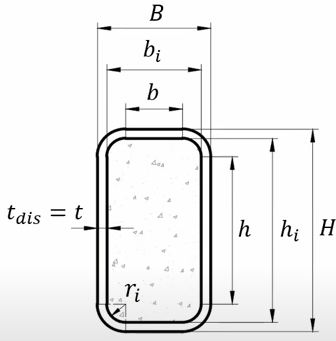

- 
$$B$$


- 
$$H$$


- 
$$t_{\textrm{nominal}}$$


B = 300;           % [mm]
H = 300;           % [mm]
t_nominal = 8;   % [mm]
r = 8;           % [mm]

### Procedimiento

**Conversión de unidades**

B = B / 10;                         % [cm]
H = H / 10;                         % [cm]
t_nominal = t_nominal / 10;         % [cm]
L = L * 100;                        % [cm]

Propiedades geométricas previas en función de la siguiente figura:

**Dimensiones**

- 
$$t={0\ldotp 93t}_{\textrm{nom}}$$


- 
$$b=B-3t$$


- 
$$h=H-3t$$


- $r_i =0\ldotp 5t$ para relaciones $h/t$, $b/t$

- $r_i =t$ para áreas, módulos de sección y momentos de inercia.

- 
$$h_i =H-2t$$


- 
$$b_i =B-2t$$


t = 0.93 * t_nominal;           % [cm]
b = B - 3 * t;                  % [cm]
h = H - 3 * t;                  % [cm]
ri_relaciones = 0.5 * t;        % [cm]
ri = t;                         % [cm]
bi = B - 2 * t;                 % [cm]
hi = H - 2 * t;                 % [cm]

**Áreas**

- 
$$A_c =b_i h_i -t^2 \left(4-\pi \right)$$


- 
$$A_g =\textrm{BH}-\left({\left(r_i +t\right)}^2 \left(4-\pi \right)\right)$$


- 
$$A_s =A_g -A_c$$


switch r
    case 0
        Ac = bi * hi;                               % [cm2]
        Ag = B * H;                                 % [cm2]
    otherwise
        Ac = bi * hi - t ^ 2 * (4 - pi);            % [cm2]
        Ag = B * H - ((ri + t) ^ 2 * (4 - pi));     % [cm2]
end

As = Ag - Ac;                                       % [cm2]

**Inercia y radio de giro del acero**

- 
$$I_{\textrm{gx}} =\frac{\left(B-2r_i -2t\right)H^3 }{12}+\frac{\left(r_i +t\right)}{6}{\left(H-2t-2r_i \right)}^3 +\frac{\left(9\pi^2 -64\right){\left(r_i +t\right)}^4 }{36\pi }+{\pi \left(r_i +t\right)}^2 {\left(\frac{4\left(r_i +t\right)}{3\pi }+\frac{H-2r_i -2t}{2}\right)}^2$$


- 
$$I_{\textrm{cx}} =\frac{\left(B-2r_i -2t\right){h_i }^3 }{12}+\frac{r_i }{6}{\left(H-2t-2r_i \right)}^3 +\frac{\left(9\pi^2 -64\right){r_i }^4 }{36\pi }+{\pi r_i }^2 {\left(\frac{4r_i }{3\pi }+\frac{H-2r_i -2t}{2}\right)}^2$$


- 
$$r_{\textrm{sx}} =\sqrt{\frac{I_{\textrm{sx}} }{A_s }}$$


- 
$$I_{\textrm{gy}} =\frac{\left(H-2r_i -2t\right)B^3 }{12}+\frac{\left(r_i +t\right)}{6}{\left(B-2t-2r_i \right)}^3 +\frac{\left(9\pi^2 -64\right){\left(r_i +t\right)}^4 }{36\pi }+{\pi \left(r_i +t\right)}^2 {\left(\frac{4\left(r_i +t\right)}{3\pi }+\frac{B-2r_i -2t}{2}\right)}^2$$


- 
$$I_{\textrm{cy}} =\frac{\left(H-2r_i -2t\right){b_i }^3 }{12}+\frac{r_i }{6}{\left(B-2t-2r_i \right)}^3 +\frac{\left(9\pi^2 -64\right){r_i }^4 }{36\pi }+{\pi r_i }^2 {\left(\frac{4r_i }{3\pi }+\frac{B-2r_i -2t}{2}\right)}^2$$


- 
$$r_{\textrm{sy}} =\sqrt{\frac{I_{\textrm{sy}} }{A_s }}$$


switch r
    case 0
        Igx = 1 / 12 * B * H ^ 3;                           % [cm4]
        Icx = 1 / 12 * bi * hi ^ 3;                         % [cm4]
    otherwise
        Igx = (B - 2 * ri - 2 * t) * H ^ 3 / 12 + ...       % [cm4]
            (ri + t) / 6 * (H - 2 * t - 2 * ri) ^ 3 + ...
            (9 * pi ^ 2 - 64) * (ri + t) ^ 4 / (36 * pi) + ...
            pi * (ri + t) ^ 2 * (4 * (ri + t) / (3 * pi) + (H - 2 * ri - 2 * t) / 2) ^ 2;
        Icx = (B - 2 * ri - 2 * t) * hi ^ 3 / 12 + ...      % [cm4]
            ri / 6 * (H - 2 * t - 2 * ri) ^ 3 + ...
            (9 * pi ^ 2 - 64) * ri ^ 4 / (36 * pi) + ...
            pi * ri ^ 2 * (4 * ri / (3 * pi) + (H - 2 * ri - 2 * t) / 2) ^ 2;
end
Isx = Igx - Icx;                                            % [cm4]
rsx = sqrt(Isx / As);                                       % [cm]

switch r
    case 0
        Igy = 1 / 12 * H * B ^ 3;                           % [cm4]
        Icy = 1 / 12 * hi * bi ^ 3;                         % [cm4]
    otherwise       
        Igy = (H - 2 * ri - 2 * t) * B ^ 3 / 12 + ...       % [cm4]
            (ri + t) / 6 * (B - 2 * t - 2 * ri) ^ 3 + ...
            (9 * pi ^ 2 - 64) * (ri + t) ^ 4 / (36 * pi) + ...
            pi * (ri + t) ^ 2 * (4 * (ri + t) / (3 * pi) + (B - 2 * ri - 2 * t) / 2) ^ 2;
        Icy = (H - 2 * ri - 2 * t) * bi ^ 3 / 12 + ...      % [cm4]
            ri / 6 * (B - 2 * t - 2 * ri) ^ 3 + ...
            (9 * pi ^ 2 - 64) * ri ^ 4 / (36 * pi) + ...
            pi * ri ^ 2 * (4 * ri / (3 * pi) + (B - 2 * ri - 2 * t) / 2) ^ 2;
end
Isy = Igy - Icy;                                            % [cm4]
rsy = sqrt(Isy / As);                                       % [cm]

**Módulo elástico y módulo plástico del acero**

- 
$$S_{\textrm{sx}} =\frac{2I_{\textrm{sx}} }{H}$$


- 
$$S_{\textrm{sy}} =\frac{2I_{\textrm{sy}} }{B}$$


- 
$$Z_{\textrm{sx}} =\bar{y} A_s$$


- 
$$Z_{\textrm{sy}} =\bar{x} A_s$$


Donde:

- 
$$\bar{y} =\frac{2}{A_s }\left(\left(\frac{\pi }{2}{\left(r_i +t\right)}^2 \left(\frac{4\left(r_i +t\right)}{3\pi }+\frac{H-2r_i -2t}{2}\right)\right)-\left(\frac{\pi }{2}r_i^2 \left(\frac{4r_i }{3\pi }+\frac{H-2r_i -2t}{2}\right)\right)+\left(\left(B-2r_i -2t\right)t\left(\frac{H}{2}-\frac{t}{2}\right)\right)+\left(t\frac{{\left(H-2r_i -2t\right)}^2 }{4}\right)\right)$$


- 
$$\bar{x} =\frac{2}{A_s }\left(\left(\frac{\pi }{2}{\left(r_i +t\right)}^2 \left(\frac{4\left(r_i +t\right)}{3\pi }+\frac{B-2r_i -2t}{2}\right)\right)-\left(\frac{\pi }{2}r_i^2 \left(\frac{4r_i }{3\pi }+\frac{B-2r_i -2t}{2}\right)\right)+\left(\left(H-2r_i -2t\right)t\left(\frac{B}{2}-\frac{t}{2}\right)\right)+\left(t\frac{{\left(B-2r_i -2t\right)}^2 }{4}\right)\right)$$


Ssx = 2 * Isx / H;            % [cm3]
Ssy = 2 * Isy / B;            % [cm3]

yc = 2 / As * ((pi / 2 * (ri + t) ^ 2 * (4 * (ri + t) / (3 * pi) + (H - 2 * ri - 2 * t) / 2)) - ...
    (pi / 2 * ri ^ 2 * (4 * ri / (3 * pi) + (H - 2 * ri - 2 * t) / 2)) + ...
    ((B - 2 * ri - 2 * t) * t * (H / 2 - t / 2)) + ...
    (t * (H - 2 * ri - 2 * t) ^ 2 / 4));    % [cm]
Zsx = yc * As;                % [cm3]

xc = 2 / As * ((pi / 2 * (ri + t) ^ 2 * (4 * (ri + t) / (3 * pi) + (B - 2 * ri - 2 * t) / 2)) - ...
    (pi / 2 * ri ^ 2 * (4 * ri / (3 * pi) + (B - 2 * ri - 2 * t) / 2)) + ...
    ((H - 2 * ri - 2 * t) * t * (B / 2 - t / 2)) + ...
    (t * (B - 2 * ri - 2 * t) ^ 2 / 4));    % [cm]
Zsy = xc * As;                % [cm3]

**Constante torsional**

- 
$$J_s =\frac{4A_p^2 t}{p}$$


Donde:

- 
$$A_p =\left(H-t\right)\left(B-t\right)-R_c^2 \left(4-\pi \right)$$


- 
$$p=2\left(\left(H-t\right)+\left(B-t\right)\right)-\left(2R_c \left(4-\pi \right)\right)$$


- 
$$R_c =\frac{2r_i +t}{2}$$


Rc = (2 * ri + t) / 2;                            % [cm]
p = 2 * ((H - t) + (B - t)) - 2 * Rc * (4 - pi);  % [cm]
Ap = (H - t) * (B - t) - Rc ^ 2 * (4 - pi);       % [cm2]
Js = 4 * Ap ^ 2 * t / p;                          % [cm4]

#### Paso 1: Curva de interacción A, B, C, D, E sin considerar efectos de longitud

En contrar los puntos A, B, C, D, E que forman la curva de interacción sin considerar efectos de longitud.

**Punto A (compresión axial pura)**


$$P_A =F_y A_s +0\ldotp 85{f_c }^{\prime } A_c$$



$$M_A =0$$


PA = Fy * As + 0.85 * fc * Ac;      % [kgf]
PA = PA / 1000;                     % [tonf]
MA = 0;

**Punto D (momento nominal máximo)**


$$P_D =\frac{0\ldotp 85{f_c }^{\prime } A_c }{2}$$



$$M_D =F_y Z_{\textrm{sx}} +\frac{0\ldotp 85{f_c }^{\prime } Z_c }{2}$$


Donde:

- 
$$Z_c =\frac{b_i h_i^2 }{4}$$


Zc = bi * hi ^ 2 / 4;

PD = 0.85 * fc * Ac / 2;                % [kgf]
PD = PD / 1000;                         % [tonf]
MD = Fy * Zsx + 0.85 * fc * Zc / 2;     % [kgf·cm]
MD = MD / 1e5;                          % [tonf·m]

**Punto B (flexión pura)**


$$P_B =0$$



$$M_B =M_D -F_y Z_{\textrm{sn}} -\frac{0\ldotp 85{f_c }^{\prime } Z_{\textrm{cn}} }{2}$$


Donde:

- 
$$Z_{\textrm{sn}} =2{\textrm{th}}_n^2$$


- 
$$Z_{\textrm{cn}} =b_i h_n^2$$


- 
$$h_n =\frac{0\ldotp 85{f_c }^{\prime } A_c }{2\left(0\ldotp 85{f_c }^{\prime } b_i +4{\textrm{tF}}_y \right)}\le \frac{h_i }{2}$$


hn = 0.85 * fc * Ac / (2 * (0.85 * fc * bi + 4 * t * Fy));
Zcn = bi * hn ^ 2;
Zsn = 2 * t * hn ^ 2;

PB = 0;
MB = (MD * 1e5) - Fy * Zsn - 0.85 * fc * Zcn / 2;   % [kgf·cm]
MB = MB / 1e5;                                      % [tonf·m]

**Punto C (punto intermedio)**


$$P_C =0\ldotp 85{f_c }^{\prime } A_c$$



$$M_C =M_B$$


PC = 0.85 * fc * Ac;        % [kgf]
PC = PC / 1000;             % [tonf]
MC = MB;                    % [tonf·m]

**Punto E (opcional)**

El punto E es un punto opcional dado que ayuda definir mejor la curva de interacción.


$$P_E =\frac{0\ldotp 85{f_c }^{\prime } A_c }{2}+0\ldotp 85{f_c }^{\prime } b_i h_E +4F_y {\textrm{th}}_E$$



$$M_E =M_D -F_y Z_{\textrm{sE}} -\frac{0\ldotp 85{f_c }^{\prime } Z_{\textrm{cE}} }{2}$$


Donde:

- $h_E =\frac{h_n }{2}+\frac{H}{4}$, con $h_n =1\ldotp 21\;\textrm{in}=3\ldotp 07\;\textrm{cm}$ desde el Punto B

- 
$$Z_{\textrm{cE}} =b_i h_E^2$$


- 
$$Z_{\textrm{sE}} =2{\textrm{th}}_E^2$$


hn = 3.07;                  % [cm]
hE = hn / 2 + H / 4;        % [cm]
ZcE = bi * hE ^ 2;          % [cm3]
ZsE = 2 * t * hE ^ 2;       % [cm3]

PE = 0.85 * fc * Ac / 2 + 0.85 * fc * bi * hE + 4 * Fy * t * hE;
PE = PE / 1000;
ME = (MD * 1e5) - Fy * ZsE - 0.85 * fc * ZcE / 2;
ME = ME / 1e5;

**Guardar los puntos y graficar**

P = [PA PE PC PD PB];       % Cargas
M = [MA ME MC MD MB];       % Momentos

plot(M, P, "--ko", "MarkerFaceColor", "k", ...
    "DisplayName", "Curva nominal (sin efectos longitudinales)")

#### Paso 2: Curva de interacción A', B', C', D', E' considerando efectos de longitud

En contrar los puntos A', B', C', D', E' que forman la curva de interacción considerando efectos de longitud.


$$P_{\textrm{no}} =P_A$$


Pno = PA;


$$C_3 =0\ldotp 6+2\left(\frac{A_s }{A_c +A_s }\right)\le 0\ldotp 9$$


Si el valor es mayor a 0.9, entonces se toma el valor de 0.9.

C3 = min(0.6 + 2 * As / (As + Ac), 0.9);


$${\textrm{EI}}_{\textrm{eff}} =E_s I_{\textrm{sy}} +E_s I_{\textrm{sr}} +C_3 E_c I_{\textrm{cy}}$$


Icy = 1 / 12 * bi * hi ^ 3;             % [cm4]
EIeff = Es * Isy + C3 * Ec * Icy;       % [kgf/cm2]


$$P_e =\pi^2 \frac{\left({\textrm{EI}}_{\textrm{eff}} \right)}{{\left(\textrm{KL}\right)}^2 }$$


Donde $K=1\ldotp 0$ de acuerdo al análisis del método directo.

K = 1;
Pe = pi ^ 2 * EIeff / (K * L) ^ 2;              % [kgf]
Pe = Pe / 1000;                                 % [tonf]

*(AISC Specification Equation I2-2)* Si $\frac{P_{\textrm{no}} }{P_e }\le 2\ldotp 25$, entonces $P_n =P_{\textrm{no}} \left(0\ldotp {658}^{\frac{P_{\textrm{no}} }{P_e }} \right)$. Pero si $\frac{P_{\textrm{no}} }{P_e }>2\ldotp 25$, entonces $P_n =0\ldotp 877P_e$.

if Pno / Pe <= 2.25
    Pn = Pno * (0.658 ^ (Pno / Pe));
else
    Pn = 0.877 * Pe;
end


$$\lambda =\frac{P_n }{P_{\textrm{no}} }$$


lambda = Pn / Pno;

**Guardar puntos y graficar**


$${P_X }^{\prime } =\lambda P_X$$



$${M_X }^{\prime } =M_X$$


Donde $X=A,B,C,D,E$.

Pp = lambda * P;
Mp = M;

hold on
plot(Mp, Pp, "-.ko", "MarkerFaceColor", "w", ...
    "DisplayName", "Curva nominal (con efectos longitudinales)")

#### Paso 3: Curva de diseño A'', B'', C'', D'', E'' y verificar adecuación de miembros

En contrar los puntos A'', B'', C'', D'', E'' que forman la curva de diseño.

**LRFD**


$${{P_X }^{\prime } }^{\prime } =\phi_c {P_X }^{\prime }$$



$${{M_X }^{\prime } }^{\prime } =\phi_b {M_X }^{\prime }$$


Donde $\phi_c =0\ldotp 75$ y $\phi_b =0\ldotp 90$.

phi_c = 0.75;
phi_b = 0.90;

Ppp_LRFD = phi_c * Pp;
Mpp_LRFD = phi_b * Mp;

plot(Mpp_LRFD, Ppp_LRFD, "-ks", "MarkerFaceColor", "k", ...
    "DisplayName", "Curva de diseño - LRFD")

**ASD**


$${{P_X }^{\prime } }^{\prime } =\frac{{P_X }^{\prime } }{\Omega_c }$$



$${{M_X }^{\prime } }^{\prime } =\frac{{M_X }^{\prime } }{\Omega_b }$$


Donde $\Omega_c =2\ldotp 00$ y $\Omega_b =1\ldotp 67$.

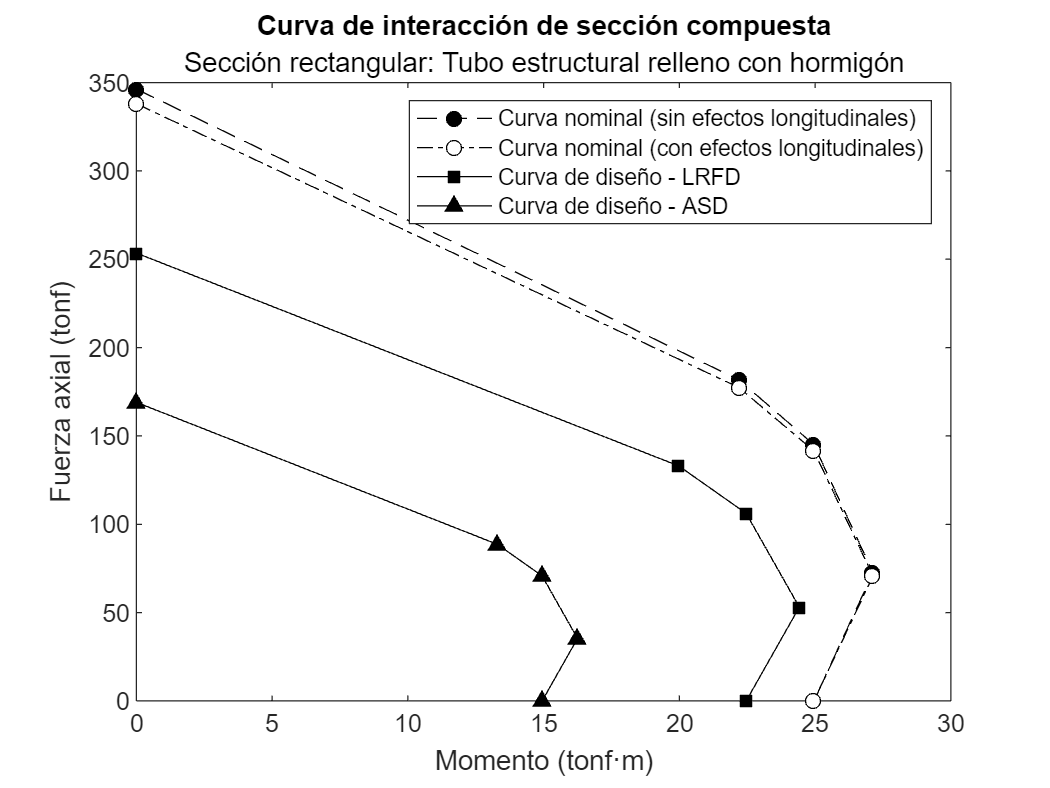

omega_c = 2.00;
omega_b = 1.67;

Ppp_ASD = Pp / omega_c;
Mpp_ASD = Mp / omega_b;

plot(Mpp_ASD, Ppp_ASD, "-k^", "MarkerFaceColor", "k", ...
    "DisplayName", "Curva de diseño - ASD")
hold off
legend
xlabel("Momento (tonf·m)")
ylabel("Fuerza axial (tonf)")
title("Curva de interacción de sección compuesta")
subtitle("Sección rectangular: Tubo estructural relleno con hormigón")

### Resultados

Curva de interacción mostrada anteriormente.

## Referencias

- American Institute of Steel Construction (AISC). (2022). **Specification for Structural Steel Buildings** (ANSI/AISC 360-22). American Institute of Steel Construction.

- Segui, W. T. (2017). **Steel Design** (6th ed.). Cengage Learning.

- Williams, M. S., & Addenbrooke, M. I. (2020). **Structural Steelwork: Design to Limit State Theory** (4th ed.). CRC Press.